# Creates Figures 1 and 2 of original paper with all desired tasks

Used this to recreate figure 1 original paper, but with cleaner looking plots and easier to change in Illustrator

- compare temporal evolution of metrics within frequency bands and tasks, i.e., reproduce figures 1 and S1 from the paper for the rest of the tasks. For this, compare all the time points within one frequency band and task (e.g., not just baseline and t1,t2, etc.)

First retreive Master Data Set

clear;
DF = dfmaster('cogtestlist',{'PVT'});


Getting GPSD during PVT Task. . . . . . . . . . . . -done

Getting Network Props during PVT: . . . . . . . . . . . . -done


Choose the network property to plot and analyize

clearvars -except DF 
desired_ntwprop = 'deg_w'; % change this to the desired network property


Get Data Set

% Get Your Data Set
df_grp          = grpAndCleanDf(DF, {'cogtest', 'condition', 'run', 'band_ord', 'sbj'}, desired_ntwprop, removetask= 'KDT');


KDT Task task is removed from this data frame


df_grp = sortrows(df_grp,"band_ord","ascend");
df_grp.band_run_cat = ordinal(strcat(cellstr(df_grp.band_ord),num2str(df_grp.run)));      


Run Tests

cogtask_list    = unique(df_grp.cogtest);
condition_list  = {'control', 'light'}; 
band_list       = unique(df_grp.band_ord);
runpair_list   = nchoosek(0:4, 2);

sig_pairs = cell(numel(cogtask_list),2, 4, 10);
intcept = [1 6 11 16]; 
for task_idx = 1:numel(cogtask_list)
    for cond_idx = 1:2
        for band_idx = 1:4
            cogtask = cogtask_list(task_idx);        
            condition = condition_list{cond_idx};    
            band_name = band_list(band_idx);
  
            % Compare pairs of runs 
            for runpair_idx = 1:10
                run_i = runpair_list(runpair_idx,1);
                if run_i == 0
                    run_i_idx = (df_grp.cogtest == cogtask) & (df_grp.condition == 'baseline') & (df_grp.band_ord == band_name);
                else
                    run_i_idx = (df_grp.cogtest == cogtask) & (df_grp.condition == condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_i);                
                end

                run_j           = runpair_list(runpair_idx,2);                 
                run_j_row = (df_grp.cogtest == cogtask) & (df_grp.condition == condition) & (df_grp.band_ord == band_name) & (df_grp.run == run_j);

                df_run_i        = df_grp(run_i_idx,:);                
                df_run_j        = df_grp(run_j_row,:);

                [h_runi_vs_runj,P,CI,STATS] = ttest(df_run_i.mean_Y,df_run_j.mean_Y);
                if h_runi_vs_runj == 1
                    sig_pairs{task_idx, cond_idx,band_idx,runpair_idx}= intcept(band_idx) + [run_i run_j] ;              
                end
            end
        end             
       
    end
end


Plot and Visualize Figure 1 Results

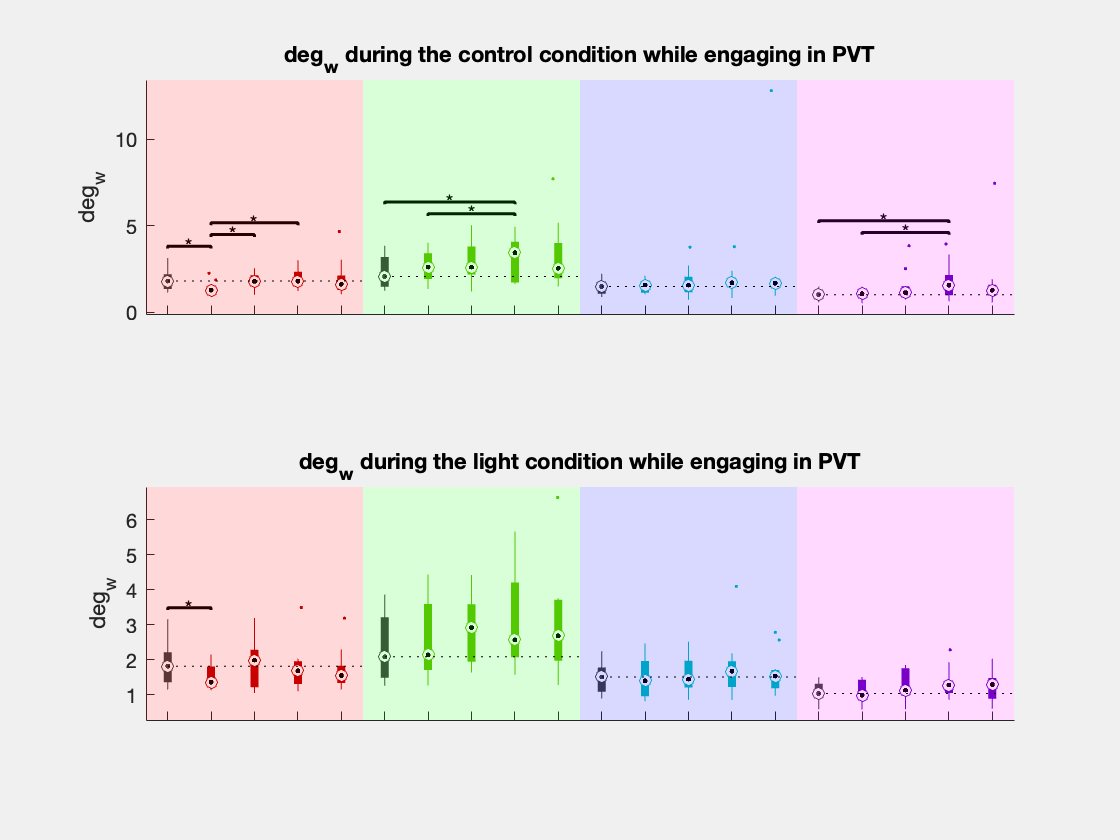

% LETS PLOT
close all force;
figure('Visible','on');
ax_subplot_idx = reshape(1:numel(cogtask_list)*2,2,[]);

ax_subplot_idx = [1 numel(cogtask_list)+1;2 numel(cogtask_list)+2;3 numel(cogtask_list)+3];

extractdftask = @(cogtask,desired_condition) df_grp(df_grp.cogtest == cogtask & (df_grp.condition == desired_condition | df_grp.condition == 'baseline'),:);
makeboxplot = @(df,task_idx,cond_idx,ax) boxplot(ax, df.mean_Y,df.band_run_cat,...
    'PlotStyle','compact','Symbol','.','ColorGroup',df.band_ord,'GroupOrder',cellstr(unique(df.band_run_cat,'stable')));
ax = [];
fscolor_set = {'r','g','b','m'};
for task_idx = 1:numel(cogtask_list)
    for cond_idx = 1:2
        cogtask = cogtask_list(task_idx);              
        condition = condition_list{cond_idx};
        df      = extractdftask(cogtask,condition);
        grpsum  = groupsummary(df,{'band_ord','run','band_run_cat'},{'median'}, {'mean_Y'});
        med_set = grpsum.median_mean_Y(grpsum.run == 0);
        
        % Plot
        ax = subplot(2,numel(cogtask_list),ax_subplot_idx(task_idx,cond_idx));
        ax_bxp_dta  = makeboxplot(df, task_idx,cond_idx,ax);        
        box off
        set(ax_bxp_dta(:,intcept),'Color', [.25 .25 .25],'MarkerEdgeColor', [.25 .25 .25]);

        for band_idx = 1:4
            sp = squeeze( sig_pairs(task_idx,cond_idx,band_idx,:) )';
            sp(cellfun(@isempty, sp)) = [];        
            if not(isempty(sp))
                hold on;
                sigstar(sp);
            end         
    
            a = intcept(band_idx);

            set(ax,'XTick',0:21);
            xmin = a -.5;

            xmax = xmin + 5;

            ymin = min(ylim);
            ymax = max(ylim);
            v = [xmin ymin; xmax ymin; xmax ymax; xmin ymax];
            f = [1 2 3 4];
            patch('Faces',f,'Vertices',v,'FaceColor',fscolor_set{band_idx},'FaceAlpha',.15,'EdgeColor','none')

            line([xmin+.5 xmax],[med_set(band_idx) med_set(band_idx)],'LineStyle',':','Color','k');
        end
        infostr = sprintf('%s during the %s condition while engaging in %s', desired_ntwprop, condition, cogtask);

        ylabel(ax,desired_ntwprop);
        title(ax,infostr);           
  
    end
end

# Functions

### Extract subset of master data frame and average accross channels, bands and subjects

function df_grouped = grpAndCleanDf(DF, groupingvars, desired_ntwprop, opts)
    arguments
        DF
        groupingvars
        desired_ntwprop 
        opts.removetask = 'None';
    end
    extdf = @(cogtask, ntw, sbj) DF( ((DF.cogtest == cogtask)) & any((DF.ntwprop == ntw),2)  &  ismember(DF.sbj, sbj),:);
    df_pvt      = extdf('PVT', desired_ntwprop, goodsbj('PVT'));
    df_gonogo   = extdf('GoNogo', desired_ntwprop, goodsbj('GoNogo'));    
    df_kdt      = extdf('KDT', desired_ntwprop, goodsbj('KDT'));
    df_math   = extdf('Math', desired_ntwprop, goodsbj('Math'));     
    
    if ~all(ismember(opts.removetask, {'None', 'Math', 'KDT'}))
        error('LUIS: you are only allowed to remove the Math task or KDT (case sensitive');
    end

    if ismember({'NONE'}, opts.removetask)
        df = [df_pvt;df_gonogo; df_math; df_kdt];
        fprintf('\nAll Tasks will be concatenated in this data frame\n') 

    elseif all(ismember({'Math', 'KDT'},opts.removetask))
        df = [df_pvt;df_gonogo];
        fprintf('\nMath Task AND KDT task are removed from this data frame\n')                     
    elseif ismember({'Math'},opts.removetask)
        df = [df_pvt;df_gonogo; df_kdt];       
        fprintf('\nMath Task task is removed from this data frame\n')     
    elseif ismember({'KDT'},opts.removetask)  
        df = [df_pvt;df_gonogo; df_math];
        fprintf('\nKDT Task task is removed from this data frame\n')     
    end



    df_grouped = varfun(@mean, df, "InputVariables","Y","GroupingVariables",groupingvars);
    df_grouped = dfrmcats(df_grouped);

end


% function setylim(df_grp, cogtask, ntwprop, ax,opts)
%     arguments
%         df_grp, cogtask, ntwprop, ax
%         opts.axisbreakinterval = nan
%     end
% 
%     cogtask = string(cogtask);
%     ntwprop =  string(ntwprop);   
% 
%     
%         if strcmp('gpsd', ntwprop)
%             if strcmp('PVT', cogtask) || strcmp('GoNogo', cogtask)             
% %                 ax.YLim = [1.5 3.5]; % both start at 1.5, but go nogo goes to 3.5 and pvt to 3
%                 axis(ax, "tight")
%             else
%                 axis(ax, "tight") % for both tasks automatically sets to [1.5 3]
% 
%             end
%         end
% 
%     
% 
% 
%     if ~isnan(opts.axisbreakinterval)
%         breakYAxes(ax, asd)
%     end
% 
% 
% end